## Exploration of the data in moodle


addpath('./matlab/nifti_tools/')
dataPath = './data/case_1/';

%% ── LOAD DATA ────────────────────────────────────────────────────────────────

% Load the 4D multi-echo T2 image: dimensions are [x, y, z, echo_time]
% Each volume along the 4th dimension corresponds to a different echo time (TE)
d = load_nii([dataPath 'case01-qt2_reg.nii.gz']);
img = double(d.img);  % Convert to double for numerical precision

% Load echo times (TEs) in milliseconds — one value per volume in img
TEs = load([dataPath 'case01-TEs.txt']);
nTE = length(TEs);

% Middle slice index along z-axis, used for 2D visualisation of the brain
midSlice = round(size(img, 3) / 2);

% Load the brain mask: binary volume where 1 = brain, 0 = skull/background
% Used to restrict analysis to brain tissue only
m = load_nii([dataPath 'case01-mask.nii.gz']);
mask = logical(m.img);  % Convert to logical for indexing

% Load tissue segmentation probabilities: dimensions are [x, y, z, class]
% Each of the 6 volumes gives the probability of a voxel belonging to that class
s = load_nii([dataPath 'case01-seg.nii.gz']);
segProb = s.img;

% Convert from probability maps to a single integer label per voxel
% max(..., [], 4) finds the class with the highest probability along dimension 4
% seg now contains values 1–6, one label per voxel
[~, seg] = max(segProb, [], 4);
seg(~mask) = 0;  % Set non-brain voxels to 0 (outside mask)

disp('Tissue class labels found inside brain mask:');

Tissue class labels found inside brain mask:


disp(unique(seg(mask))')

     1     2     3     4     5     6



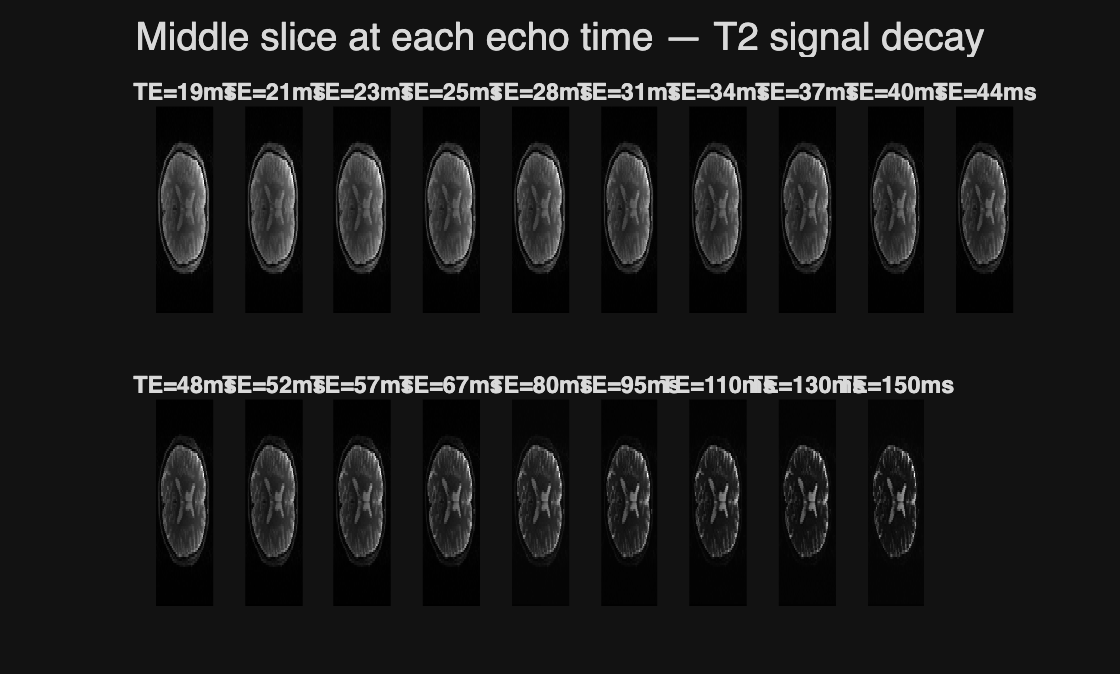


%% ── PLOT 1: Brain at each echo time ─────────────────────────────────────────
%
% WHAT IT SHOWS:
%   A grid of 2D brain slices, one per echo time (TE).
%   As TE increases, signal decays due to T2 relaxation — the brain gets
%   progressively darker. Different tissues decay at different rates:
%   CSF decays slowly (long T2 ~2000ms), white matter decays fast (short T2 ~70ms).
%
% WHAT TO LOOK FOR:
%   - Early TEs: bright image, all tissues visible
%   - Late TEs: most brain tissue dark, CSF (ventricles) stays bright longest
%   - This confirms T2 signal decay is happening as expected

figure;
for i = 1:nTE
    subplot(2, ceil(nTE/2), i);
    imagesc(img(:,:,midSlice,i));   % Show middle slice at echo time i
    colormap gray;
    axis off;
    title(sprintf('TE=%.0fms', TEs(i)));
end
sgtitle('Middle slice at each echo time — T2 signal decay');

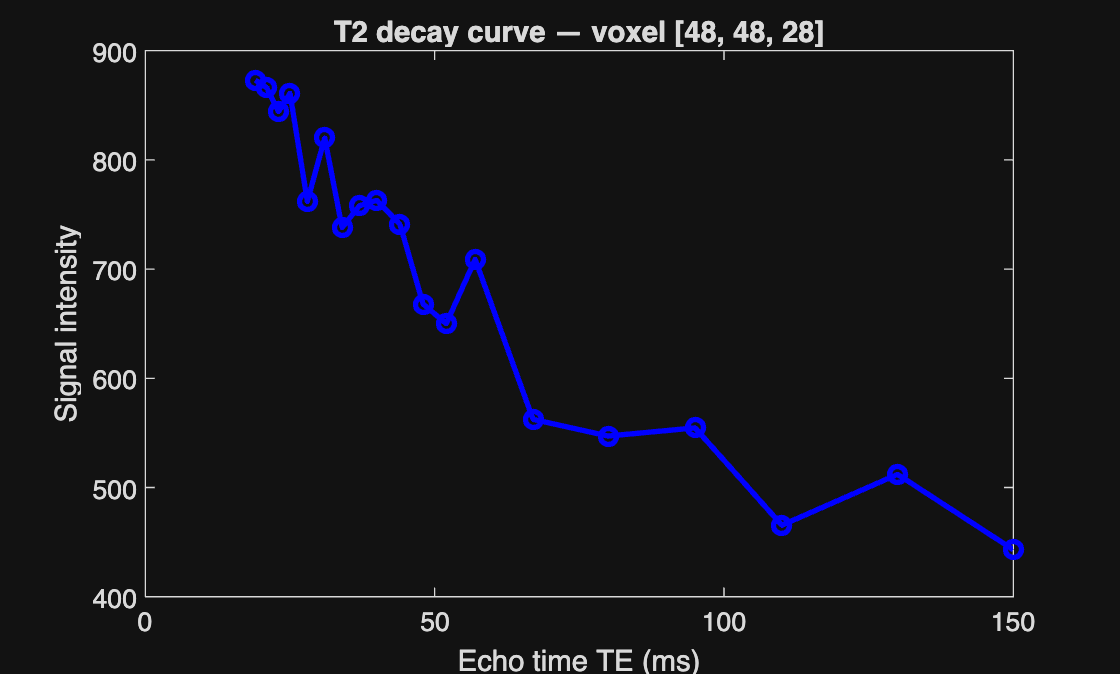


%% ── PLOT 2a: Single voxel decay curve (linear scale) ────────────────────────
%
% WHAT IT SHOWS:
%   The MRI signal at a single voxel plotted against echo time.
%   This is the raw T2 decay curve: S(TE) = S0 * exp(-TE/T2)
%   The signal starts high at short TE and falls exponentially.
%
% WHAT TO LOOK FOR:
%   - A smooth decreasing curve confirms the voxel has a good signal
%   - If the signal is noisy or non-monotonic, the voxel may be in a
%     problematic region (e.g. partial volume, motion artefact)

x = 48; y = 48; z = midSlice;  % Coordinates of the chosen voxel
signal = squeeze(img(x, y, z, :));  % Extract signal across all TEs

figure;
plot(TEs, signal, 'bo-', 'LineWidth', 2);
xlabel('Echo time TE (ms)');
ylabel('Signal intensity');
title(sprintf('T2 decay curve — voxel [%d, %d, %d]', x, y, z));

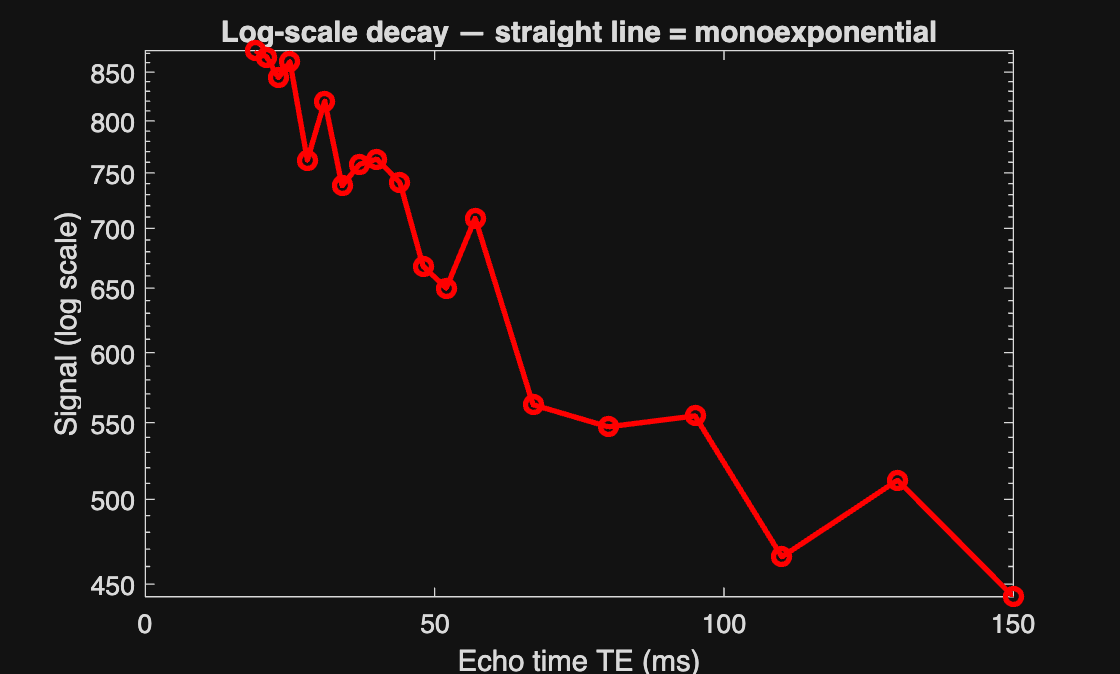


%% ── PLOT 2b: Single voxel decay curve (log scale) ───────────────────────────
%
% WHAT IT SHOWS:
%   The same decay curve as above but with a logarithmic y-axis.
%   If the decay is truly monoexponential (single T2 component),
%   log(S) vs TE should be a straight line: log(S) = log(S0) - TE/T2
%
% WHAT TO LOOK FOR:
%   - Straight line → monoexponential decay → one tissue compartment dominates
%   - Curved line → multiexponential decay → multiple compartments (e.g. myelin
%     water + intra/extracellular water), motivating the 2-compartment model

figure;
semilogy(TEs, signal, 'ro-', 'LineWidth', 2);
xlabel('Echo time TE (ms)');
ylabel('Signal (log scale)');
title('Log-scale decay — straight line = monoexponential');

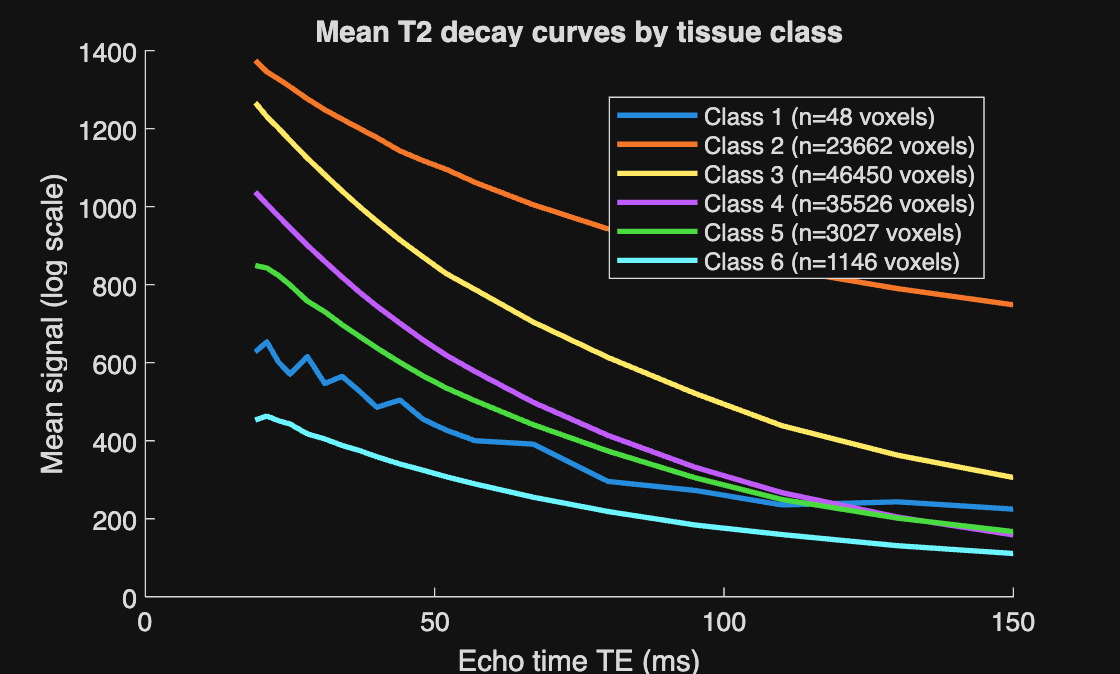


%% ── PLOT 3: Mean decay curves per tissue class ───────────────────────────────
%
% WHAT IT SHOWS:
%   The average T2 decay curve for each tissue class (CSF, GM, WM etc.),
%   computed across all voxels of that class within the brain mask.
%   Plotted on a log scale so different T2 values appear as lines with
%   different slopes.
%
% WHAT TO LOOK FOR:
%   - Each tissue should have a distinct slope (= 1/T2):
%       CSF:  very shallow slope → long T2 (~2000 ms) → slow decay
%       GM:   moderate slope     → medium T2 (~80 ms)
%       WM:   steepest slope     → short T2 (~70 ms)  → fast decay
%   - Well-separated lines confirm your segmentation is working correctly
%   - If lines overlap, there may be partial volume effects or seg errors

tissueLabels = unique(seg(mask));   % Find all class labels present in brain
colors = lines(length(tissueLabels));  % Assign a distinct colour to each class

figure; hold on;
for k = 1:length(tissueLabels)
    t = tissueLabels(k);

    % Find all voxel indices belonging to this tissue class, within the mask
    voxIdx = find(seg == t & mask);

    % Compute mean signal across all voxels of this class, at each TE
    meanSig = zeros(1, nTE);
    for te = 1:nTE
        vol = img(:,:,:,te);           % Extract 3D volume at echo time te
        meanSig(te) = mean(vol(voxIdx));  % Average signal over tissue voxels
    end

    % Plot on log scale — slope of each line reflects 1/T2 for that tissue
    semilogy(TEs, meanSig, 'Color', colors(k,:), 'LineWidth', 2, ...
             'DisplayName', sprintf('Class %d (n=%d voxels)', t, length(voxIdx)));
end

xlabel('Echo time TE (ms)');
ylabel('Mean signal (log scale)');
legend('Location', 'best');
title('Mean T2 decay curves by tissue class');

## The model being fitted

You want to estimate two parameters per voxel: **S₀** (signal at TE=0) and **T2** (relaxation time in ms).


$$S\left(\textrm{TE}\right)=\textrm{S0}\cdot \;e^{-\textrm{TE}/T_2 }$$


%% ── SECTION 1: LOAD DATA ─────────────────────────────────────────────────────
% Load the 4D multi-echo T2 image: dimensions are [x, y, z, echo_time]
% Each volume along the 4th dimension corresponds to a different echo time (TE)
d = load_nii([dataPath 'case01-qt2_reg.nii.gz']);
img = double(d.img);

% Load echo times in milliseconds — one value per volume in img
TEs = load([dataPath 'case01-TEs.txt']);
nTE = length(TEs);

% Load brain mask: binary volume where 1 = brain, 0 = skull/background
m = load_nii([dataPath 'case01-mask.nii.gz']);
mask = logical(m.img);

% Clip negative values to 0 — physically impossible but can appear from noise
% log() of a negative number is undefined so we must remove them
img(img < 0) = 0;


%% ── SECTION 2: WHOLE-BRAIN OLS FIT (vectorised) ─────────────────────────────
%
% WHAT IT DOES:
%   Fits S(TE) = S0 * exp(-TE/T2) to every brain voxel simultaneously.
%   Taking log linearises the model: log(S) = log(S0) - TE/T2
%   This is now a linear system solvable with matrix division (A\b).
%
% RESULT:
%   Two 3D maps — S0 (initial signal) and T2 (relaxation time in ms)
%   for every voxel in the brain.

% Design matrix A: col 1 = ones (intercept = log(S0)), col 2 = TE (slope = -1/T2)
A = [ones(nTE, 1), TEs(:)];

% Take log of entire 4D image to linearise the exponential decay
s = log(img);
s(~isfinite(s)) = 0;  % Replace -Inf (from log(0)) and NaN with 0

% Solve least squares for ALL voxels at once using matrix division
% Reshape from 4D [x,y,z,TE] to 2D [nVoxels, nTE], transpose to [nTE, nVoxels]
% Result 'new' has 2 rows: row1 = log(S0), row2 = slope (-1/T2)
new = A \ reshape(s, numel(s)/nTE, nTE)';

% Convert fitted parameters back to interpretable units
new(1,:) = exp(new(1,:));   % log(S0) → S0  (signal amplitude)
new(2,:) = -1./new(2,:);    % slope   → T2 in ms

% Reshape result back into 3D spatial maps
% [:,:,:,1] = S0 map,  [:,:,:,2] = T2 map
new = reshape(new', [size(img,1), size(img,2), size(img,3), 2]);

% Extract and mask the parameter maps
S0_map = new(:,:,:,1) .* mask;
T2_map = new(:,:,:,2) .* mask;

% Sanity check — median T2 in brain should be ~70-100ms for healthy adults
fprintf('Median T2 in brain mask: %.1f ms\n', median(T2_map(mask & T2_map > 0)));

Median T2 in brain mask: 78.6 ms


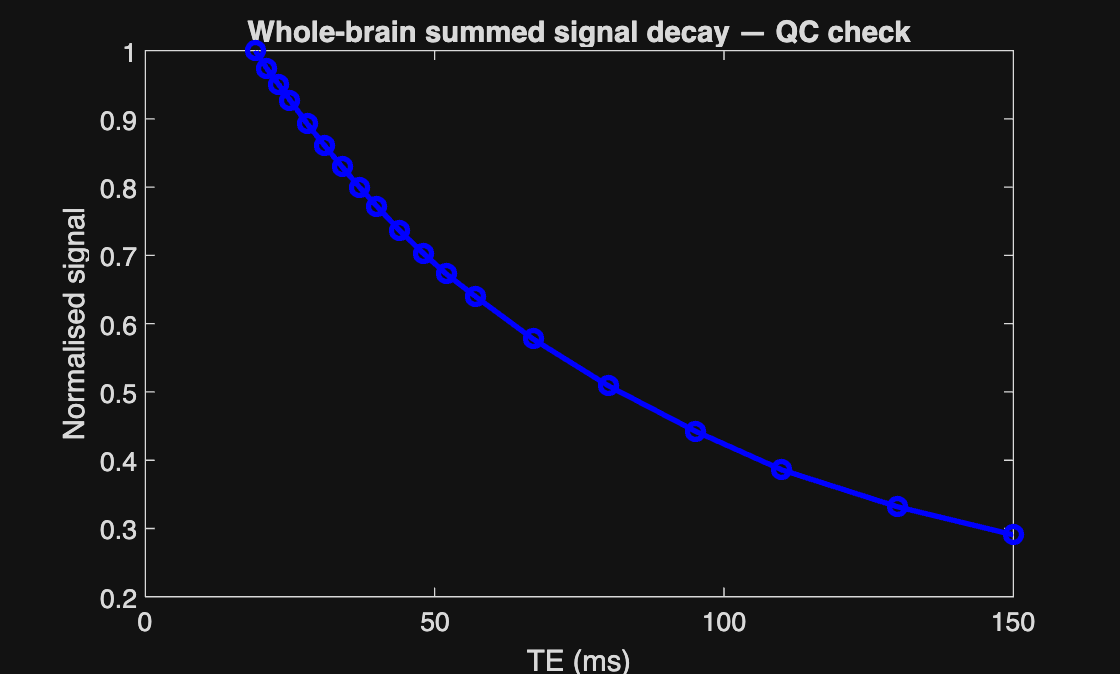

%% ── SECTION 3: QC — SUMMED SIGNAL OVER TIME ─────────────────────────────────
%
% WHAT IT SHOWS:
%   Collapses all brain voxels into a single decay curve by summing
%   signal across the whole brain at each TE, then normalising to [0,1].
%   This is a quick quality check before fitting — confirms signal decays
%   smoothly and monotonically as expected from T2 relaxation.
%
% WHAT TO LOOK FOR:
%   - Smooth monotonic decrease from 1.0 → confirms data is valid
%   - Any sudden jumps or non-monotonic behaviour → motion artefact or
%     data loading error

y_sum = squeeze(sum(sum(sum(img .* mask, 1), 2), 3));
y_sum = y_sum / max(y_sum);  % Normalise to [0,1]

figure;
plot(TEs, y_sum, 'bo-', 'LineWidth', 2);
xlabel('TE (ms)'); ylabel('Normalised signal');
title('Whole-brain summed signal decay — QC check');

%% ── SECTION 4: SINGLE VOXEL — LOG-LINEAR (OLS) FIT ──────────────────────────
%
% WHAT IT DOES:
%   Fits the monoexponential model to a single voxel using log-linearisation.
%   Taking log converts S(TE) = S0*exp(-TE/T2) into:
%       log(S) = log(S0) - (1/T2)*TE
%   which is a straight line: intercept = log(S0), slope = -1/T2
%
% PROS: Very fast — solved in one matrix operation
% CONS: Taking log amplifies noise at long TEs where signal is weak

x = 48; y = 48; z = round(size(img,3)/2);
signal = squeeze(img(x, y, z, :));  % Extract decay curve at this voxel

% Solve linear system: p(1) = log(S0), p(2) = -1/T2
p = A \ log(signal);
T2_ols = -1 / p(2);      % Convert slope to T2 in ms
S0_ols = exp(p(1));       % Convert intercept to S0
y1 = exp(A * p);          % Reconstruct fitted curve for plotting

fprintf('OLS fit  → S0 = %.1f,  T2 = %.1f ms\n', S0_ols, T2_ols);

OLS fit  → S0 = 920.2,  T2 = 187.0 ms


%% ── SECTION 5: SINGLE VOXEL — NON-LINEAR (NLLS) FIT ─────────────────────────
%
% WHAT IT DOES:
%   Fits S(TE) = S0*exp(-TE/T2) directly in the signal domain without
%   taking the log. Iteratively minimises the sum of squared residuals:
%       min  sum[ y(TE) - S0*exp(-TE/T2) ]^2
%
% PROS: Statistically correct — treats noise properly in signal domain
%       More accurate than OLS especially at long TEs / low SNR
% CONS: Iterative → much slower than OLS
%       Needs a good initial guess to converge correctly
%       (here we use the OLS result as the starting point)

options = optimset('Display', 'off');

% lsqnonlin finds [S0, T2] minimising the residual vector
% Initial guess [S0_ols, T2_ols] from OLS fit above
% Lower bounds [0, 0] prevent physically impossible negative values
p2 = lsqnonlin(@(p)(signal - p(1)*exp(-TEs(:)/p(2))), ...
               [S0_ols, T2_ols], [0, 0], [], options);
y2 = p2(1) * exp(-TEs / p2(2));  % Reconstruct fitted curve

fprintf('NLLS fit → S0 = %.1f,  T2 = %.1f ms\n', p2(1), p2(2));

NLLS fit → S0 = 944.3,  T2 = 171.7 ms


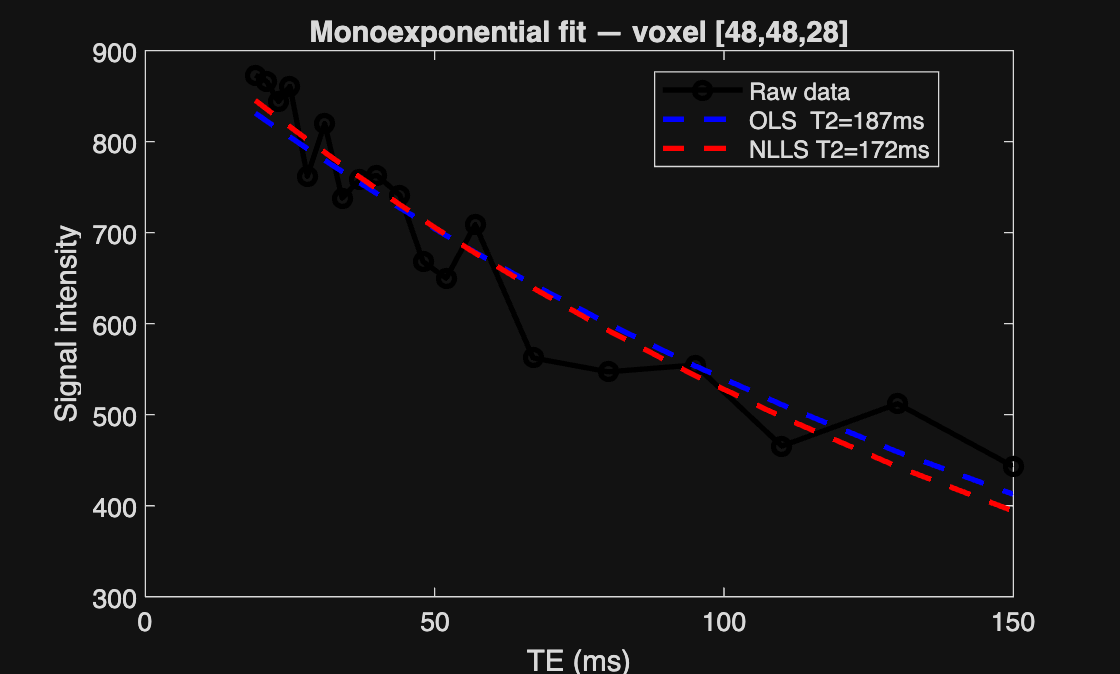

%% ── SECTION 6: PLOT — Compare raw data, OLS and NLLS ────────────────────────
%
% WHAT IT SHOWS:
%   Overlays the raw signal with both fitted curves for visual comparison.
%   Both fits should track the data, but NLLS typically fits better at
%   long TEs where OLS tends to underestimate due to log noise amplification.
%
% WHAT TO LOOK FOR:
%   - If OLS and NLLS give similar T2 → voxel has good SNR, both methods work
%   - If they diverge → noisy voxel, NLLS is more trustworthy
%   - Neither fitting a straight line on log scale → multiexponential signal
%     (motivates the 2-compartment model in Task 3)

figure;
plot(TEs, signal, 'ko-', 'LineWidth', 2, 'DisplayName', 'Raw data'); hold on;
plot(TEs, y1,     'b--', 'LineWidth', 2, 'DisplayName', sprintf('OLS  T2=%.0fms',  T2_ols));
plot(TEs, y2,     'r--', 'LineWidth', 2, 'DisplayName', sprintf('NLLS T2=%.0fms', p2(2)));
xlabel('TE (ms)'); ylabel('Signal intensity');
legend('Location', 'best');
title(sprintf('Monoexponential fit — voxel [%d,%d,%d]', x, y, z));

%% ── SECTION 7: SPEED COMPARISON ─────────────────────────────────────────────
%
% WHAT IT SHOWS:
%   Times 1000 repetitions of each fitting method.
%   This is critical for whole-brain analysis: with ~100,000 brain voxels,
%   a method that takes 1ms per voxel would take 100 seconds total.
%   OLS is typically ~100x faster than NLLS.
%
% WHAT TO LOOK FOR:
%   - OLS should be <0.01s for 1000 fits
%   - NLLS will be significantly slower
%   - This trade-off (speed vs accuracy) is a key discussion point in Task 2

tic;
for i = 1:1000
    p_temp = A \ log(signal);
end
fprintf('1000 OLS fits:  %.3f s\n', toc);

1000 OLS fits:  0.010 s



tic;
for i = 1:1000
    lsqnonlin(@(p)(signal - p(1)*exp(-TEs(:)/p(2))), ...
              [S0_ols, T2_ols], [0,0], [], options);
end
fprintf('1000 NLLS fits: %.3f s\n', toc);

1000 NLLS fits: 1.420 s


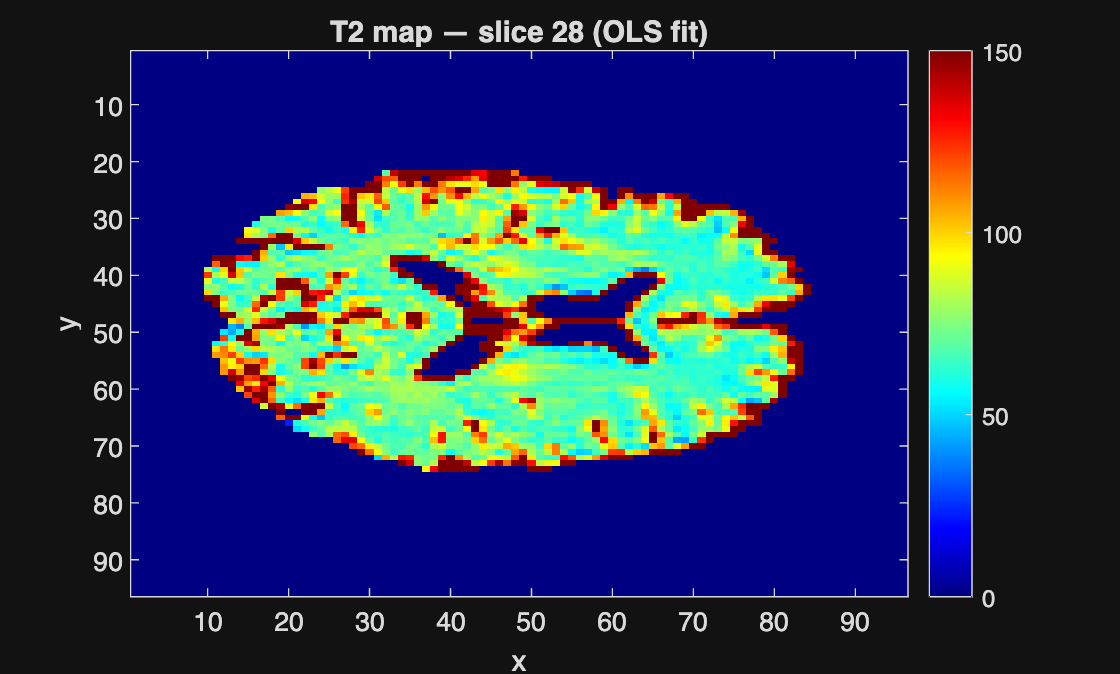

%% ── SECTION 8: T2 MAP VISUALISATION ─────────────────────────────────────────
%
% WHAT IT SHOWS:
%   A 2D colour map of T2 values across the middle brain slice.
%   Each pixel colour represents the fitted T2 time in ms for that voxel.
%   This is the key output of Task 2 — a quantitative T2 map of the brain.
%
% WHAT TO LOOK FOR:
%   - WM regions (inner brain): shorter T2 ~60-80ms → cooler colours
%   - GM regions (outer cortex): longer T2 ~80-100ms → warmer colours
%   - CSF (ventricles, centre): very long T2 ~500ms+ → bright/saturated
%   - Voxels outside brain: should be 0 (masked out)
%   - Unrealistic values (negative T2 or T2 > 500ms) → fitting failed,
%     usually at brain edges with low SNR

midSlice = round(size(img,3)/2);

% Extract T2 map for middle slice
T2_display = T2_map(:,:,midSlice);

% Fix 1: Take only the real part — complex values come from log of negative numbers
T2_display = real(T2_display);

% Fix 2: Remove physically impossible values
% Negative T2 = fitting failed, T2 > 500ms = likely CSF or artefact
T2_display(T2_display < 0)   = 0;
T2_display(T2_display > 500) = 0;

% Fix 3: Remove any remaining NaN or Inf
T2_display(~isfinite(T2_display)) = 0;

% Apply brain mask — zero out non-brain voxels
T2_display = T2_display .* mask(:,:,midSlice);

figure;
imagesc(T2_display);
colormap jet; colorbar;
caxis([0 150]);
title(sprintf('T2 map — slice %d (OLS fit)', midSlice));
xlabel('x'); ylabel('y');

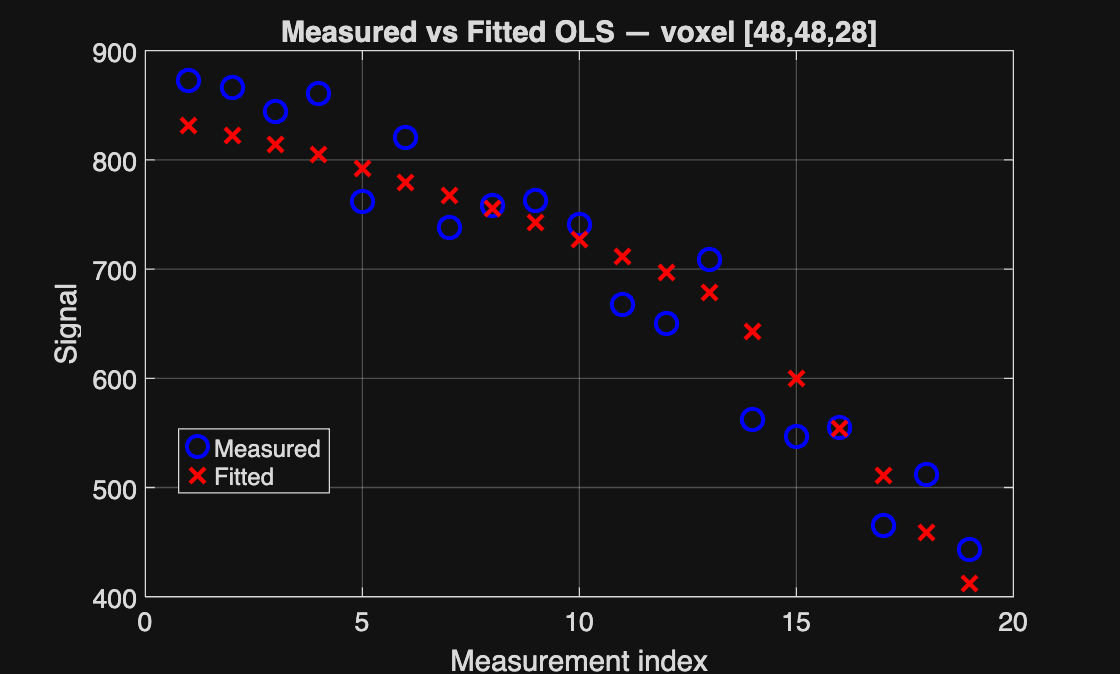

%% ── PLOT: Measured vs OLS Fitted (Daniel's style) ───────────────────────────

% Extract signal at single voxel
x = 48; y = 48; z = round(size(img,3)/2);
signal = squeeze(img(x, y, z, :));

% OLS fit
p    = A \ log(signal);
y1   = exp(A * p);
T2_ols = -1/p(2);
S0_ols = exp(p(1));

figure;
plot(1:nTE, signal, 'bo', 'MarkerSize', 8, ...
     'LineWidth', 1.5, 'DisplayName', 'Measured');   % blue circles
hold on;
plot(1:nTE, y1, 'rx', 'MarkerSize', 8, ...
     'LineWidth', 1.5, 'DisplayName', 'Fitted');      % red crosses
hold off;

xlabel('Measurement index');
ylabel('Signal');
legend('Location', 'best');
title(sprintf('Measured vs Fitted OLS — voxel [%d,%d,%d]', x, y, z));
grid on;